clear all;
format long e
syms Vf
t = linspace(0,1,100);
% Volume fraction
   %Vf = 0.5;
   Vm = 1.0 - Vf;
% Now calculate the stiffness matrix of fibre
% Fibre is transversely isotropic with following properties in GPa
  E1 = 80;
  E2 = 80;
  E3 = E2;
%
  G12 = 33.33;
  G13 = 33.33;
%
  G23 = 33.33;
%  
  nu_12 = 0.2;
  nu_13 = nu_12;
%  
  nu_23 = E2/(2.0 * G23) - 1.0;
%
  nu_21 = nu_12 * E2/E1;
  nu_31 = nu_13 * E3/E1;
  nu_32 = nu_23 * E3/E2;
% Initialization
  s = zeros(6,6);
  Cf = zeros(6,6);
  Cm = zeros(6,6);
%  
    s(1,1)=1.0/E1;
    s(2,2)=1.0/E2;
    s(3,3)=1.0/E3;
%    
    s(1,2)=-nu_21/E2;
    s(1,3)=-nu_31/E3;
%    
    s(2,1)=-nu_21/E2;
    s(2,3)=-nu_32/E3;
%    
    s(3,1)=-nu_13/E1; 
    s(3,2)=-nu_23/E2;
% Following order is according order in Abaqus
    s(4,4)=1.0/G12;
    s(5,5)=1.0/G13;
    s(6,6)=1.0/G23;
    Cf = inv(s);

Cf =      8.889037076553748e+01     2.222592691384369e+01     2.222592691384370e+01                         0                         0                         0
     2.222592691384369e+01     8.889481728460922e+01     2.223481728460923e+01                         0                         0                         0
     2.222592691384370e+01     2.223481728460923e+01     8.889481728460923e+01                         0                         0                         0
                         0                         0                         0     3.333000000000000e+01                         0                         0
                         0                         0                         0                         0     3.333000000000000e+01                         0
                         0                         0                         0                         0                         0     3.333000000000000e+01


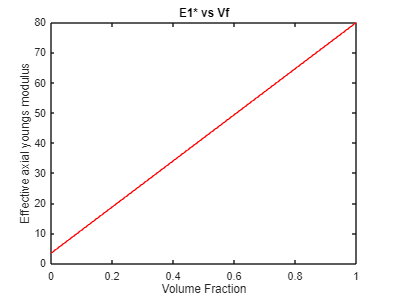

% Calculate the stiffness matrix of matrix
% Matrix is isotropic with following properties
  E0 = 3.35;
  XNU = 0.35;
%  
     XX = E0 * (1.0 - XNU)/((1.0 - 2.0 * XNU)*(1.0 + XNU));
     YY = E0 * XNU/((1.0 - 2.0 * XNU)*(1.0 + XNU));
     ZZ = E0 /(2.0 * (1.0 + XNU));
%
            for I = 1:3
               for J = 1:3
                  Cm(I,J) = YY;
               end
               Cm(I,I) = XX;
               Cm(I+3,I+3) = ZZ;
            end
Mf = G23;
Mm = E0 /(2.0 * (1.0 + XNU));
E1_eff = E1*Vf+E0*Vm;
E1_eff = double(subs(E1_eff,Vf,t));
plot(t,E1_eff,'r','Linewidth',0.2);
title("E1* vs Vf")
xlabel("Volume Fraction")
ylabel("Effective axial youngs modulus")

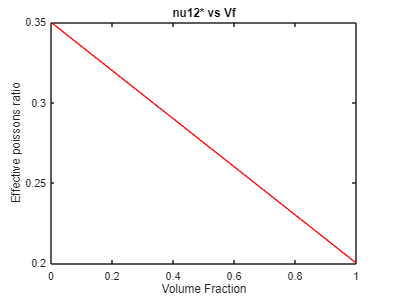

nu12_eff = nu_12*Vf+XNU*Vm;
nu12_eff = double(subs(nu12_eff,Vf,t));
plot(t,nu12_eff,'r','Linewidth',0.2);
title("nu12* vs Vf")
xlabel("Volume Fraction")
ylabel("Effective poissons ratio")

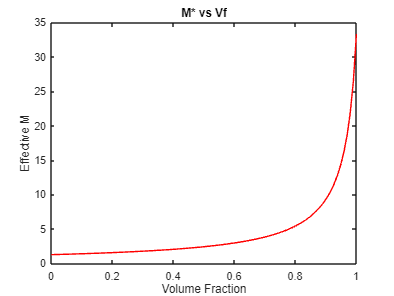

M_eff = 1/((Vf/Mf)+(Vm/Mm));
M_eff = double(subs(M_eff,Vf,t));
plot(t,M_eff,'r','Linewidth',0.2);
title("M* vs Vf")
xlabel("Volume Fraction")
ylabel("Effective M")